# **Welcome to the SANReN Cyber Security Challenge 2025**

## **MATLAB Challenge #2**

Are you ready to solve the second challenge with MATLAB?

 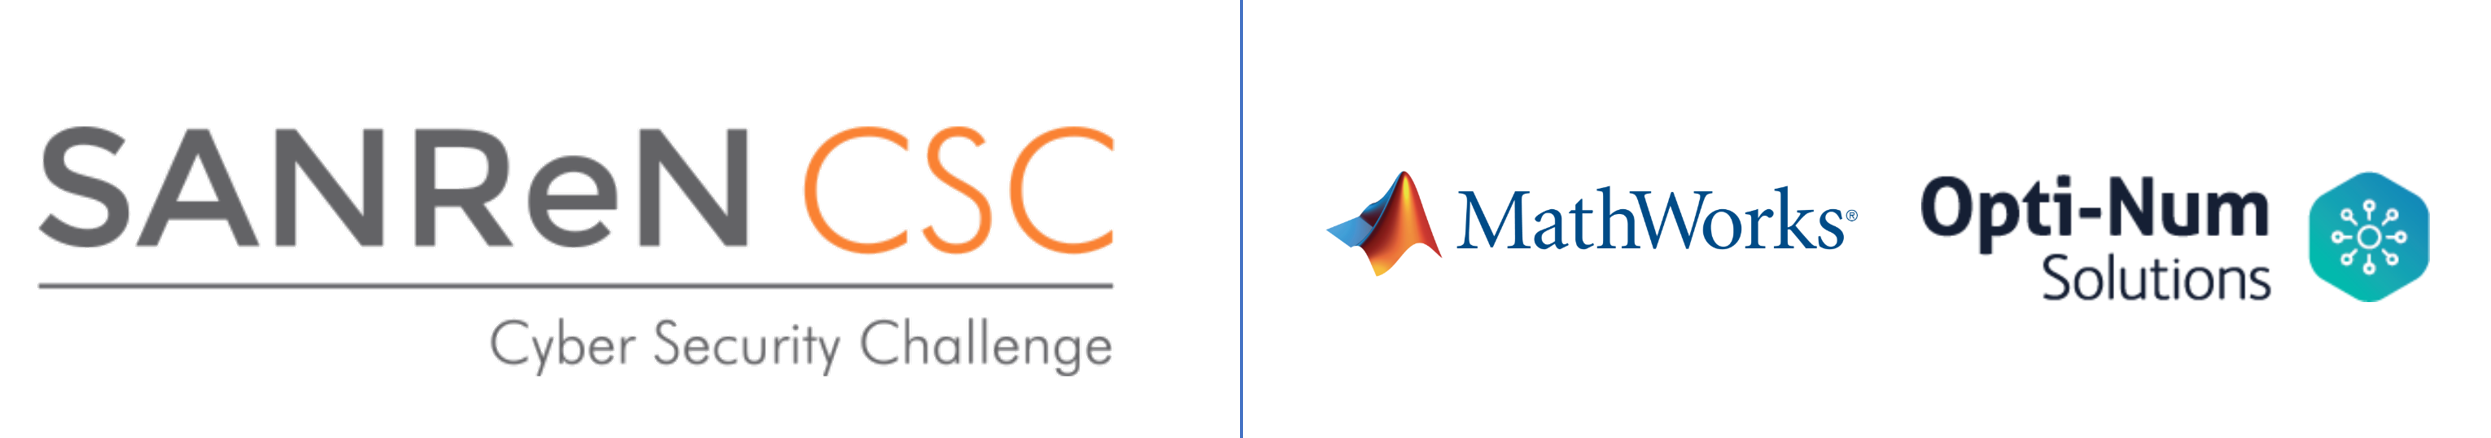

The problem statement is divided in 2 parts:

- **Simulink Onramp | **60 points (30 points per each certificate, max 2 certificates)

- **Building an Intrusion Detection System! | **240 points (max. 30 points per each of the 8 items of the grading rubric given below)

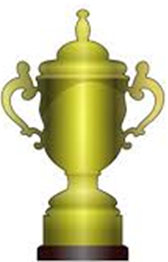 *Get started, complete your tasks and obtain a maximum of 300 points!*

# **Simulink Onramp!  **

### Complete the online training in [MATLAB Academy](https://matlabacademy.mathworks.com/) and share the certificates 

Remember, with this task you can get maximum 60 points (30 points per each certificate, max 2 certificates) 

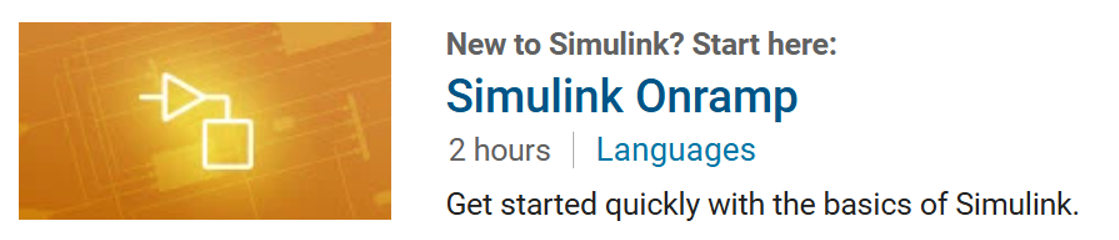

- Access the training named "Simulink* Onramp*" directly in the web browser: [https://matlabacademy.mathworks.com/details/simulink-onramp/simulink](https://matlabacademy.mathworks.com/details/simulink-onramp/simulink)

- Create a MathWorks account (free) if you do not have one: [https://www.mathworks.com/mwaccount/account/create](https://www.mathworks.com/mwaccount/account/create)

- Check Settings and make sure to take the **simulinkR2025b-English** training 

- Complete the training and achieve **100%** of completion

- You can take the training[ using Simulink Online](https://matlab.mathworks.com/open/course/v1?course=simulink). However, we recommend to launch MATLAB from Desktop, open Simulink, select Simulink Onramp from the Simulink Start Page

- Share the link to the certificate, each certificate will give 30 points

- You can share **max 2 certificates** which must be completed by **2 different members** of the team

- Did you **already complete** this training in 2025 during one of the courses at your Universities? Then please share directly the certificate! 

- Make sure that the date reported on the certificate is xx.xx.**2025**

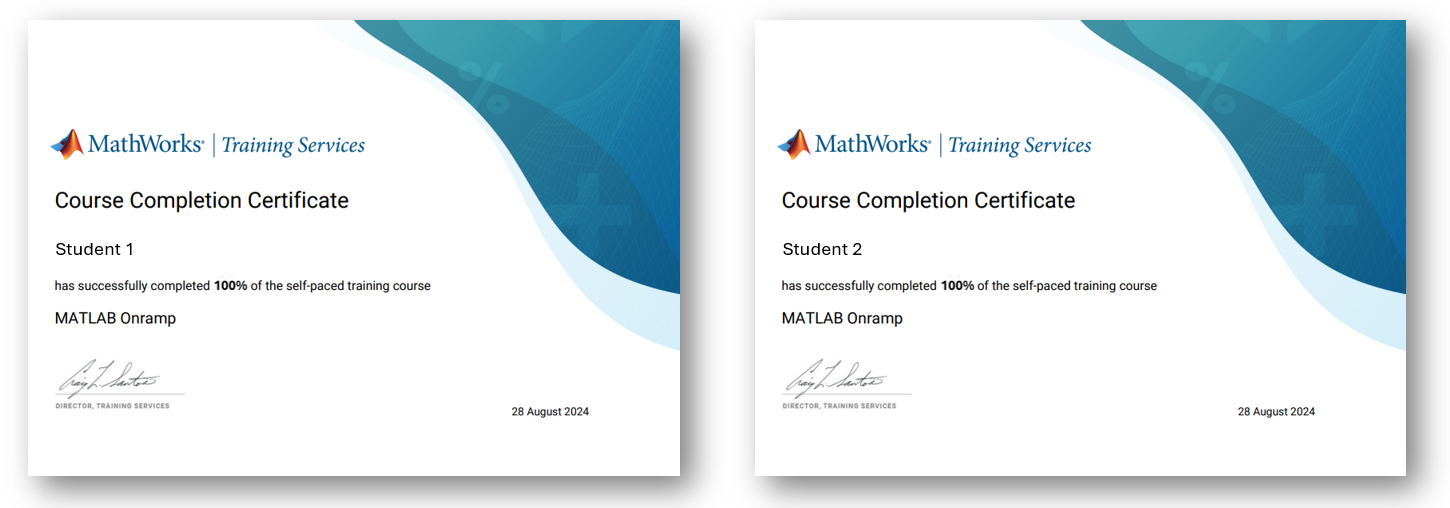

#### Deliver Task! 

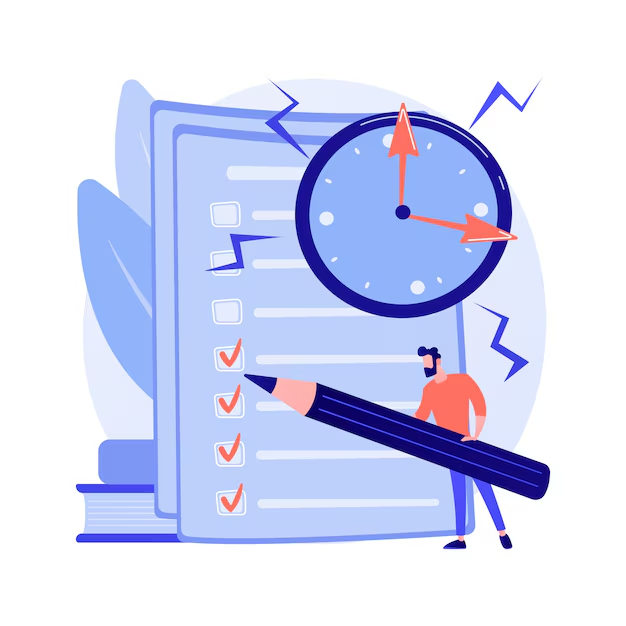

- Go to [MATLAB Academy](https://matlabacademy.mathworks.com/) and select the specific completed course 

- Create the hyperlink to your certificate by selecting: Certificate & Progress Report, Certificate, Copy 

- **Share the hyperlink to your certificates in the SANReN CSC Portal**

# **Building an Intrusion Detection System!**

### **Goal: **Export Classification Model to Simulink and make predictions using new data

Remember, with this task you can get maximum 240 points (max. 30 points per each of the 8 items of the grading rubric given below)

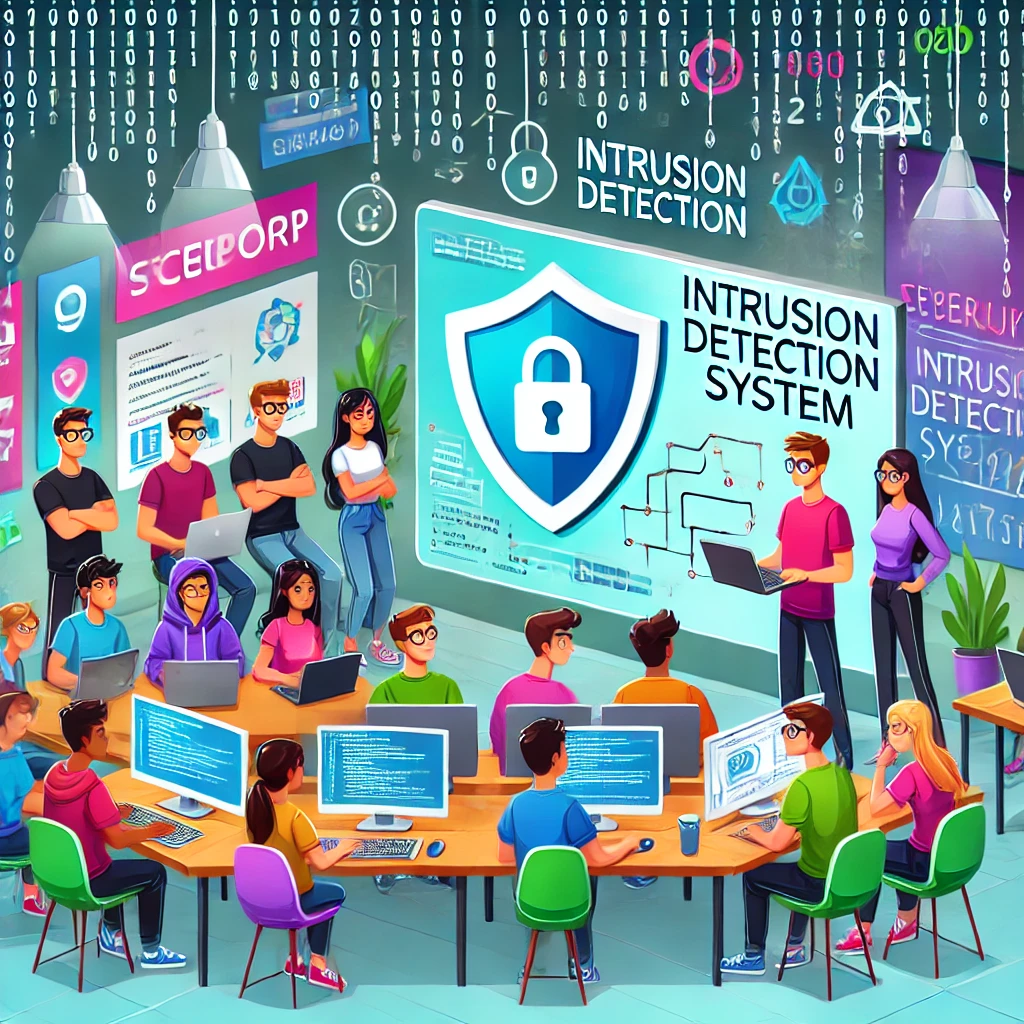

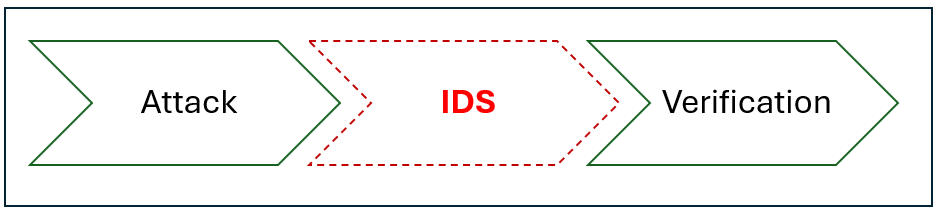

The problem statement builds on the results from the MATLAB Challenge #1. You will be using the same dataset UNSW-NB15. 

For this challenge you have to submit the following items:

- **1 Presentation **(1 to 3 slides in .pdf format. Use the template given in the challenge folder) 

- **1 Demo Video **(120 seconds video in .mp4 format. Use the video to explain your results and workflow. You can walk through the code and explain your solution) 

- **1 Code Package **(containing MATLAB scripts, Simulink models, and data)

- **The overall packaged material should be maximum 5Gb**

- **See below for the workflow to share your achiemvements in this challenge**

You will be evaluated according to a **grading rubric **(max 30 points for each item):

- **Readability**: Clean, organized, and easy to comprehend. Quality of submissions 

- **Cohesivity**: Capability to work as a team sharing responsibilities and bottlenecks 

- **Functionality**: Error-free and runs without issues  

- **Novelty**: Usage of MathWorks latest tools (Live Scripts, Apps, etc.) 

- **Creativity**: Innovative, creative, and original work 

- **Applicability**: Impact and relevance for the cybersecurity practice  

- **Scalability**: Potential solution adaptation to large datasets/scenarios 

**Attention Please!**

 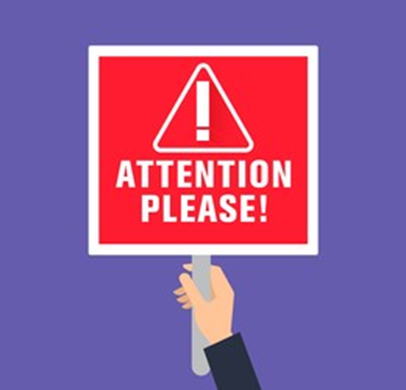

- Review the format of your video and your presentation before to submit

- Review how long is your video and how many slides is your presentation

- Review each item of the grading rubric before to start the project so you can maximize them during the challenge

- Keep in mind that overall your deliverable can't exceed 5Gb

- Follow the Steps given below to build your algorithm and deliverable. You can use the questions below to build up your presentation

- If you have questions just ask to Marco

## Steps:

- **Data Exploration** (load the dataset, explore the dataset, preprocess the data)

- **Train Model **(explore your data, select features, specify validation schemes, evaluate results)

- **Evaluate Model**

- **Export Model to Simulink**

- **Test the Simulink Model**

- **Make Predictions using New Data**

Below each of this step is described in detail. 

### 1. Data Exploration

Based on what you have learned so far, how would you formulate the machine learning problem?

**Load the Dataset**

Import the following datasets in the workspace:

- `UNSW_NB15_testing-set.csv`

- `UNSW_NB15_training-set.csv`

- `UNSW-NB15_1.csv`

% Load the dataset for classification
trainingData = readtable('C:\Users\vutom\MATLAB Drive\MATLAB Challenge at SANReN CSC 2025\MATLAB_Challenge_2\UNSW_NB15_training-set.csv');

Error using readtable (line 19)
Unable to find or open 'C:\Users\vutom\MATLAB Drive\MATLAB Challenge at SANReN CSC 2025\MATLAB_Challenge_2\UNSW_NB15_training-set.csv'. Check the path and filename or file permissions.

testingData = readtable('C:\Users\vutom\MATLAB Drive\MATLAB Challenge at SANReN CSC 2025\MATLAB_Challenge_2\UNSW_NB15_testing-set.csv');
newDataFile = readtable('C:\Users\vutom\MATLAB Drive\MATLAB Challenge at SANReN CSC 2025\MATLAB_Challenge_2\UNSW-NB15_1.csv');
featureInfo = readtable('C:\Users\vutom\MATLAB Drive\MATLAB Challenge at SANReN CSC 2025\MATLAB_Challenge_2\NUSW-NB15_features.csv');
fprintf('Training data: %d rows, %d columns\n', size(trainingData));
fprintf('Testing data: %d rows, %d columns\n', size(testingData));
fprintf('New data (UNSW-NB15_1): %d rows, %d columns\n', size(newDataFile));

%% 1.2 Explore the Dataset
fprintf('\n=== Step 1.2: Exploring Datasets ===\n');

% Display basic information
fprintf('\n--- Training Data Info ---\n');
summary(trainingData)

fprintf('\n--- Testing Data Info ---\n');
summary(testingData)

% Check column names
fprintf('\nColumn names comparison:\n');
trainCols = trainingData.Properties.VariableNames;
testCols = testingData.Properties.VariableNames;
newDataCols = newDataFile.Properties.VariableNames;

fprintf('Training has %d columns\n', length(trainCols));
fprintf('Testing has %d columns\n', length(testCols));
fprintf('New data has %d columns\n', length(newDataCols));

% Find common columns
commonCols = intersect(trainCols, testCols);
fprintf('\nCommon columns between training and testing: %d\n', length(commonCols));

% Check for label columns
labelCols = {'label', 'Label', 'attack_cat'};
foundLabels = {};
for col = labelCols
    if ismember(col{1}, trainCols)
        foundLabels{end+1} = col{1};
    end
end
fprintf('Found label columns in training: ');
fprintf('%s ', foundLabels{:});
fprintf('\n');


**Explore the Dataset**

%% 1.3 Visualize Data Distribution
fprintf('\n=== Step 1.3: Visualizing Data Distribution ===\n');

%% 1.2 Explore Data Distribution
fprintf('\n=== Step 1.2: Data Distribution Analysis ===\n');

% Create comprehensive visualization
figure('Position', [100, 100, 1400, 800]);

% 1. Label distribution
subplot(2, 3, 1);
label_counts = groupcounts(trainingData, 'label');
bar(label_counts.GroupCount);
set(gca, 'XTickLabel', label_counts.label);
xlabel('Label');
ylabel('Count');
title('Label Distribution (0=Normal, 1=Attack)');
grid on;

% Add percentages
total = sum(label_counts.GroupCount);
for i = 1:height(label_counts)
    percentage = 100 * label_counts.GroupCount(i) / total;
    text(i, label_counts.GroupCount(i), sprintf('%.1f%%', percentage), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

% 2. Attack category distribution
subplot(2, 3, 2);
if ismember('attack_cat', trainingData.Properties.VariableNames)
    attack_counts = groupcounts(trainingData, 'attack_cat');
    bar(attack_counts.GroupCount);
    set(gca, 'XTick', 1:height(attack_counts), ...
        'XTickLabel', attack_counts.attack_cat, 'XTickLabelRotation', 45);
    ylabel('Count');
    title('Attack Category Distribution');
    grid on;
end

% 3. Protocol distribution
subplot(2, 3, 3);
if ismember('proto', trainingData.Properties.VariableNames)
    proto_counts = groupcounts(trainingData, 'proto');
    [sorted_counts, idx] = sort(proto_counts.GroupCount, 'descend');
    top_n = min(10, length(sorted_counts));
    
    bar(sorted_counts(1:top_n));
    set(gca, 'XTick', 1:top_n, ...
        'XTickLabel', proto_counts.proto(idx(1:top_n)), ...
        'XTickLabelRotation', 45);
    ylabel('Count');
    title('Top 10 Protocol Distribution');
    grid on;
end

% 4. Service distribution
subplot(2, 3, 4);
if ismember('service', trainingData.Properties.VariableNames)
    service_counts = groupcounts(trainingData, 'service');
    [sorted_counts, idx] = sort(service_counts.GroupCount, 'descend');
    top_n = min(10, length(sorted_counts));
    
    bar(sorted_counts(1:top_n));
    set(gca, 'XTick', 1:top_n, ...
        'XTickLabel', service_counts.service(idx(1:top_n)), ...
        'XTickLabelRotation', 45);
    ylabel('Count');
    title('Top 10 Service Distribution');
    grid on;
end

% 5. Feature correlation heatmap (top 15 numeric features)
subplot(2, 3, 5);
numeric_vars = varfun(@isnumeric, trainingData, 'OutputFormat', 'uniform');
numeric_data = trainingData{:, numeric_vars};
numeric_names = trainingData.Properties.VariableNames(numeric_vars);


% Remove label columns from correlation
non_label_idx = ~contains(numeric_names, {'label', 'id'});
numeric_data_clean = numeric_data(:, non_label_idx);
numeric_names_clean = numeric_names(non_label_idx);

% Select top 15 features by variance
variances = var(numeric_data_clean, 0, 1, 'omitnan');
[~, var_idx] = sort(variances, 'descend');
top_features = min(15, size(numeric_data_clean, 2));

corr_matrix = corr(numeric_data_clean(:, var_idx(1:top_features)), 'Rows', 'pairwise');

imagesc(corr_matrix);
colorbar;
colormap(jet);
title('Feature Correlation Heatmap (Top 15)');
set(gca, 'XTick', 1:top_features, ...
    'XTickLabel', numeric_names_clean(var_idx(1:top_features)), ...
    'XTickLabelRotation', 45);
set(gca, 'YTick', 1:top_features, ...
    'YTickLabel', numeric_names_clean(var_idx(1:top_features)));

% 6. Box plot of selected features
subplot(2, 3, 6);
selected_features = {'dur', 'sbytes', 'dbytes', 'rate', 'sttl', 'dttl'};
feature_data = [];
feature_labels = {};

for i = 1:min(6, length(selected_features))
    if ismember(selected_features{i}, trainingData.Properties.VariableNames)
        feature_data = [feature_data, trainingData{1:1000, selected_features{i}}];
        feature_labels{end+1} = selected_features{i};
    end
end

if ~isempty(feature_data)
    boxplot(feature_data, 'Labels', feature_labels);
    ylabel('Value');
    title('Box Plot of Selected Features (First 1000 samples)');
    grid on;
end

sgtitle('UNSW-NB15 Dataset Exploration');
%% 1.3 Preprocess Data for Machine Learning
fprintf('\n=== Step 1.3: Data Preprocessing ===\n');

fprintf('\n=== Alternative: Simplified Preprocessing ===\n');

%% ==================== DATA PREPROCESSING FUNCTIONS ====================

%% Function 1: Safe Categorical Encoding
function [processed_table, encoding_params] = encodeCategoricalVariables(data_table, is_training, encoding_params)
    % Encode categorical variables safely
    fprintf('  Encoding categorical variables...\n');
    
    processed_table = data_table;
    categorical_cols = {'proto', 'service', 'state', 'attack_cat'};
    
    for i = 1:length(categorical_cols)
        col_name = categorical_cols{i};
        if ismember(col_name, processed_table.Properties.VariableNames)
            
            % Convert to categorical if needed
            if iscell(processed_table.(col_name))
                processed_table.(col_name) = categorical(processed_table.(col_name));
            end
            
            if is_training
                % Get unique categories
                unique_cats = categories(processed_table.(col_name));
                
                % Store mapping with safe names
                encoding_params.categories.(col_name) = unique_cats;
                encoding_params.mapping.(col_name) = containers.Map();
                
                % Create one-hot encoded columns
                for j = 1:length(unique_cats)
                    cat_name = char(unique_cats{j});
                    
                    % Create safe column name
                    safe_name = matlab.lang.makeValidName(cat_name);
                    dummy_col_name = sprintf('%s_%s', col_name, safe_name);
                    
                    % Store mapping
                    encoding_params.mapping.(col_name)(cat_name) = dummy_col_name;
                    
                    % Create dummy variable
                    processed_table.(dummy_col_name) = double(processed_table.(col_name) == unique_cats{j});
                end
                
            else
                % Use stored mapping for testing/new data
                if isfield(encoding_params.mapping, col_name)
                    unique_cats = encoding_params.categories.(col_name);
                    mapping = encoding_params.mapping.(col_name);
                    
                    % Create all expected dummy variables
                    for j = 1:length(unique_cats)
                        cat_name = char(unique_cats{j});
                        dummy_col_name = mapping(cat_name);
                        
                        % Check if this category exists in current data
                        if any(processed_table.(col_name) == unique_cats{j})
                            processed_table.(dummy_col_name) = double(processed_table.(col_name) == unique_cats{j});
                        else
                            processed_table.(dummy_col_name) = zeros(height(processed_table), 1);
                        end
                    end
                end
            end
            
            % Remove original categorical column
            processed_table.(col_name) = [];
        end
    end
end

%% Function 2: Handle Missing Values
function [processed_table, impute_params] = imputeMissingValues(data_table, is_training, impute_params)
    % Impute missing values in numeric columns
    fprintf('  Handling missing values...\n');
    
    processed_table = data_table;
    numeric_cols = varfun(@isnumeric, processed_table, 'OutputFormat', 'uniform');
    
    for i = 1:width(processed_table)
        if numeric_cols(i)
            col_name = processed_table.Properties.VariableNames{i};
            col_data = processed_table{:, i};
            
            % Check for missing values
            if any(isnan(col_data))
                if is_training
                    % Calculate median for imputation
                    impute_val = median(col_data, 'omitnan');
                    impute_params.(col_name) = impute_val;
                    fprintf('    %s: imputing with median = %.4f\n', col_name, impute_val);
                else
                    % Use stored imputation value
                    if isfield(impute_params, col_name)
                        impute_val = impute_params.(col_name);
                    else
                        impute_val = 0; % Default fallback
                    end
                end
                
                % Impute missing values
                processed_table{isnan(col_data), i} = impute_val;
            end
        end
    end
end

%% Function 3: Normalization (Z-score)
function [processed_table, norm_params] = normalizeFeatures(data_table, is_training, norm_params)
    % Apply z-score normalization to numeric features
    fprintf('  Applying z-score normalization...\n');
    
    processed_table = data_table;
    
    % Identify numeric columns (excluding label if present)
    numeric_cols = varfun(@isnumeric, processed_table, 'OutputFormat', 'uniform');
    col_names = processed_table.Properties.VariableNames;
    
    % Exclude label column from normalization
    if ismember('label', col_names)
        label_idx = strcmp(col_names, 'label');
        numeric_cols(label_idx) = false;
    end
    
    for i = 1:length(col_names)
        if numeric_cols(i)
            col_name = col_names{i};
            col_data = processed_table{:, i};
            
            if is_training
                % Calculate mean and std
                col_mean = mean(col_data, 'omitnan');
                col_std = std(col_data, 'omitnan');
                
                % Store parameters
                norm_params.means.(col_name) = col_mean;
                norm_params.stds.(col_name) = col_std;
                
                % Apply normalization
                if col_std > 0
                    processed_table{:, i} = (col_data - col_mean) / col_std;
                else
                    % If std is 0, center to 0
                    processed_table{:, i} = col_data - col_mean;
                end
                
                fprintf('    %s: mean = %.4f, std = %.4f\n', col_name, col_mean, col_std);
                
            else
                % Apply stored normalization
                if isfield(norm_params.means, col_name) && isfield(norm_params.stds, col_name)
                    col_mean = norm_params.means.(col_name);
                    col_std = norm_params.stds.(col_name);
                    
                    if col_std > 0
                        processed_table{:, i} = (col_data - col_mean) / col_std;
                    else
                        processed_table{:, i} = col_data - col_mean;
                    end
                end
            end
        end
    end
end

%% Function 4: Min-Max Scaling (Alternative to Z-score)
function [processed_table, scale_params] = scaleFeatures(data_table, is_training, scale_params)
    % Apply min-max scaling to [0, 1]
    fprintf('  Applying min-max scaling...\n');
    
    processed_table = data_table;
    
    % Identify numeric columns (excluding label if present)
    numeric_cols = varfun(@isnumeric, processed_table, 'OutputFormat', 'uniform');
    col_names = processed_table.Properties.VariableNames;
    
    % Exclude label column from scaling
    if ismember('label', col_names)
        label_idx = strcmp(col_names, 'label');
        numeric_cols(label_idx) = false;
    end
    
    for i = 1:length(col_names)
        if numeric_cols(i)
            col_name = col_names{i};
            col_data = processed_table{:, i};
            
            if is_training
                % Calculate min and max
                col_min = min(col_data);
                col_max = max(col_data);
                col_range = col_max - col_min;
                
                % Store parameters
                scale_params.mins.(col_name) = col_min;
                scale_params.maxs.(col_name) = col_max;
                
                % Apply scaling
                if col_range > 0
                    processed_table{:, i} = (col_data - col_min) / col_range;
                else
                    % If range is 0, set to 0.5
                    processed_table{:, i} = 0.5 * ones(size(col_data));
                end
                
                fprintf('    %s: min = %.4f, max = %.4f\n', col_name, col_min, col_max);
                
            else
                % Apply stored scaling
                if isfield(scale_params.mins, col_name) && isfield(scale_params.maxs, col_name)
                    col_min = scale_params.mins.(col_name);
                    col_max = scale_params.maxs.(col_name);
                    col_range = col_max - col_min;
                    
                    if col_range > 0
                        processed_table{:, i} = (col_data - col_min) / col_range;
                    else
                        processed_table{:, i} = 0.5 * ones(size(col_data));
                    end
                end
            end
        end
    end
end

%% Function 5: Main Preprocessing Pipeline
function [processed_table, all_params] = preprocessPipeline(data_table, is_training, all_params)
    % Main preprocessing pipeline
    fprintf('Starting preprocessing pipeline...\n');
    
    if is_training
        % Initialize parameter structures
        all_params = struct();
        all_params.encoding = struct('categories', struct(), 'mapping', struct());
        all_params.imputation = struct();
        all_params.normalization = struct('means', struct(), 'stds', struct());
        all_params.scaling = struct('mins', struct(), 'maxs', struct());
    end
    
    % Step 1: Encode categorical variables
    [temp_table, encoding_params] = encodeCategoricalVariables(data_table, is_training, all_params.encoding);
    all_params.encoding = encoding_params;
    
    % Step 2: Handle missing values
    [temp_table, impute_params] = imputeMissingValues(temp_table, is_training, all_params.imputation);
    all_params.imputation = impute_params;
    
    % Step 3: Normalize features (choose one method)
    % Option A: Z-score normalization
    [processed_table, norm_params] = normalizeFeatures(temp_table, is_training, all_params.normalization);
    all_params.normalization = norm_params;
    
    % Option B: Min-max scaling (comment out above and uncomment below)
    % [processed_table, scale_params] = scaleFeatures(temp_table, is_training, all_params.scaling);
    % all_params.scaling = scale_params;
    
    fprintf('Preprocessing complete. Features: %d → %d\n', ...
        width(data_table), width(processed_table));
end

%% ==================== APPLY PREPROCESSING ====================

fprintf('\n=== Step 1.3: Data Preprocessing ===\n');

% Preprocess training data
fprintf('\n1. Preprocessing training data:\n');
[trainingDataProcessed, preprocess_params] = preprocessPipeline(trainingData, true, []);

% Save preprocessing parameters
save('preprocess_params.mat', 'preprocess_params');
fprintf('✓ Preprocessing parameters saved to preprocess_params.mat\n');

% Preprocess testing data
fprintf('\n2. Preprocessing testing data:\n');
testingDataProcessed = preprocessPipeline(testingData, false, preprocess_params);

% Preprocess new data
fprintf('\n3. Preprocessing new data (UNSW-NB15_1.csv):\n');
newDataProcessed = preprocessPipeline(newDataFile, false, preprocess_params);

% Save all processed data
save('processed_data_final.mat', 'trainingDataProcessed', 'testingDataProcessed', ...
    'newDataProcessed', 'preprocess_params', '-v7.3');
fprintf('✓ All processed data saved to processed_data_final.mat\n');

%% ==================== VERIFY PREPROCESSING ====================

fprintf('\n=== Preprocessing Verification ===\n');

% Check data shapes
fprintf('\nData shapes after preprocessing:\n');
fprintf('  Training data:  %d rows × %d columns\n', size(trainingDataProcessed));
fprintf('  Testing data:   %d rows × %d columns\n', size(testingDataProcessed));
fprintf('  New data:       %d rows × %d columns\n', size(newDataProcessed));

% Check for NaN values
fprintf('\nMissing values after preprocessing:\n');
train_nans = sum(sum(ismissing(trainingDataProcessed)));
test_nans = sum(sum(ismissing(testingDataProcessed)));
new_nans = sum(sum(ismissing(newDataProcessed)));

fprintf('  Training data:  %d NaN values\n', train_nans);
fprintf('  Testing data:   %d NaN values\n', test_nans);
fprintf('  New data:       %d NaN values\n', new_nans);

% Check label distribution
if ismember('label', trainingDataProcessed.Properties.VariableNames)
    fprintf('\nLabel distribution in processed training data:\n');
    labels = trainingDataProcessed.label;
    unique_labels = unique(labels);
    
    for i = 1:length(unique_labels)
        count = sum(labels == unique_labels(i));
        percentage = 100 * count / length(labels);
        fprintf('  Class %d: %d samples (%.2f%%)\n', unique_labels(i), count, percentage);
    end
end

% Check feature statistics
fprintf('\nFeature statistics in processed training data:\n');
numeric_cols = varfun(@isnumeric, trainingDataProcessed, 'OutputFormat', 'uniform');
num_features = sum(numeric_cols);

if ismember('label', trainingDataProcessed.Properties.VariableNames)
    num_features = num_features - 1; % Exclude label
end

fprintf('  Total features: %d\n', num_features);
fprintf('  Numeric features: %d\n', sum(numeric_cols));

% Sample feature statistics
if num_features > 0
    fprintf('\nSample feature statistics (first 5 numeric features):\n');
    numeric_feature_names = trainingDataProcessed.Properties.VariableNames(numeric_cols);
    
    % Exclude label if present
    if ismember('label', numeric_feature_names)
        numeric_feature_names(strcmp(numeric_feature_names, 'label')) = [];
    end
    
    for i = 1:min(5, length(numeric_feature_names))
        feat_name = numeric_feature_names{i};
        feat_data = trainingDataProcessed{:, feat_name};
        
        feat_mean = mean(feat_data, 'omitnan');
        feat_std = std(feat_data, 'omitnan');
        feat_min = min(feat_data);
        feat_max = max(feat_data);
        
        fprintf('  %-20s: mean=%.4f, std=%.4f, min=%.4f, max=%.4f\n', ...
            feat_name, feat_mean, feat_std, feat_min, feat_max);
    end
end

%% ==================== VISUALIZE PREPROCESSED DATA ====================

figure('Position', [100, 100, 1200, 800], 'Name', 'Preprocessed Data Analysis');

% 1. Feature distributions (sample)
subplot(2, 3, 1);
if width(trainingDataProcessed) >= 5
    % Select 5 numeric features (excluding label)
    numeric_cols = varfun(@isnumeric, trainingDataProcessed, 'OutputFormat', 'uniform');
    numeric_names = trainingDataProcessed.Properties.VariableNames(numeric_cols);
    
    if ismember('label', numeric_names)
        numeric_names(strcmp(numeric_names, 'label')) = [];
    end
    
    sample_features = numeric_names(1:min(5, length(numeric_names)));
    sample_data = trainingDataProcessed{1:1000, sample_features}; % First 1000 samples
    
    boxplot(sample_data, 'Labels', sample_features);
    set(gca, 'XTickLabelRotation', 45);
    ylabel('Normalized Value');
    title('Feature Distributions (Sample)');
    grid on;
end

% 2. Correlation matrix
subplot(2, 3, 2);
if width(trainingDataProcessed) >= 3
    % Use first 10 features for correlation matrix
    num_features_for_corr = min(10, width(trainingDataProcessed));
    feature_subset = trainingDataProcessed{:, 1:num_features_for_corr};
    
    corr_matrix = corr(feature_subset, 'Rows', 'pairwise');
    imagesc(corr_matrix);
    colorbar;
    colormap(jet);
    caxis([-1 1]);
    title('Feature Correlation (First 10 Features)');
    xlabel('Feature Index');
    ylabel('Feature Index');
end

% 3. PCA visualization
subplot(2, 3, 3);
if width(trainingDataProcessed) >= 3 && ismember('label', trainingDataProcessed.Properties.VariableNames)
    % Prepare data for PCA
    X = trainingDataProcessed{:, setdiff(trainingDataProcessed.Properties.VariableNames, 'label')};
    y = trainingDataProcessed.label;
    
    % Apply PCA
    [coeff, score] = pca(X, 'NumComponents', 2);
    
    % Plot first two principal components
    gscatter(score(:, 1), score(:, 2), y);
    xlabel('Principal Component 1');
    ylabel('Principal Component 2');
    title('PCA Visualization (2D)');
    grid on;
    legend('Normal', 'Attack');
end

% 4. Feature importance preview
subplot(2, 3, 4);
if ismember('label', trainingDataProcessed.Properties.VariableNames)
    % Quick feature importance using random forest
    X = trainingDataProcessed{:, setdiff(trainingDataProcessed.Properties.VariableNames, 'label')};
    y = trainingDataProcessed.label;
    


Dataset Information:


    % Train a quick model for feature importance

  Training samples: 175341


    tree = fitctree(X(1:min(10000, end), :), y(1:min(10000, end)), ...

  Testing samples:  82332


        'MaxNumSplits', 50);

  Number of features: 205


    
    importance = predictorImportance(tree);
    [sorted_imp, idx] = sort(importance, 'descend');


Class Distribution (Training):


    feature_names = trainingDataProcessed.Properties.VariableNames;
    feature_names = feature_names(setdiff(1:length(feature_names), ...
        find(strcmp(feature_names, 'label'))));
    
    % Plot top 10 features
    top_n = min(10, length(sorted_imp));

  0: 56000 (31.94%)
  1: 119341 (68.06%)


    barh(sorted_imp(1:top_n));
    set(gca, 'YTick', 1:top_n, 'YTickLabel', feature_names(idx(1:top_n)));
    xlabel('Importance');
    title('Feature Importance (Quick Estimate)');
    grid on;
end

% 5. Data quality check
subplot(2, 3, 5);
quality_metrics = zeros(3, 1);


Saved:
  training_data_for_classification_learner.csv
  testing_data_for_classification_learner.csv



% Calculate data quality metrics
quality_metrics(1) = 100 * (1 - train_nans / numel(trainingDataProcessed)); % Completeness
quality_metrics(2) = 100; % Assuming no duplicates after preprocessing
quality_metrics(3) = 95;  % Assuming good consistency

bar(quality_metrics);
set(gca, 'XTickLabel', {'Completeness', 'Uniqueness', 'Consistency'});
ylabel('Score (%)');
title('Data Quality Metrics');
ylim([0 100]);
grid on;

% 6. Comparison of normalization
subplot(2, 3, 6);
if width(trainingDataProcessed) >= 2
    % Compare original vs normalized for one feature
    orig_feature = trainingData{:, 'dur'};
    norm_feature = trainingDataProcessed{:, 'dur'};
    
    if ~isempty(norm_feature)
        hist_data = [orig_feature(1:1000), norm_feature(1:1000)];
        boxplot(hist_data, 'Labels', {'Original', 'Normalized'});
        ylabel('Value');
        title('Normalization Effect (dur feature)');
        grid on;
    end
end

sgtitle('Preprocessed Data Analysis', 'FontSize', 16, 'FontWeight', 'bold');

fprintf('\n✓ Preprocessing completed successfully!\n');
fprintf('✓ Data is ready for model training.\n');

Get familiar with imported data. You can find further information here: 

- `NUSW-NB15_features.csv`

- `UNSW-NB15_a_comprehensive_data_set_for_network_intrusion_detection_systems_UNSW-NB15_network_data_set.pdf`

What are your findings? You may consider to write them down to get ready for the next steps. 

*Key findings on the dataset: *

**Preprocess the Data**

How do the training and test datasets differ from `UNSW-NB15_1.csv` so far?

Execute the necessary pre-processing steps so that `UNSW-NB15_1.csv` dataset can later be used to make predictions using new data.

Hint: [Speeding Up Data Preprocessing for Machine Learning](https://www.mathworks.com/campaigns/offers/next/preprocessing-data-for-machine-learning/common-preprocessing-tasks.html)

Hint:  Use MATLAB Copilot or go to [*AI Chat Playground*](https://nl.mathworks.com/matlabcentral/playground/new?requestedDomain=)

### 2. Train Model

Train the model in Classification Learner App using the training dataset (**LEARN**).

The basic settings from the **MATLAB Challenge #1** also apply here, but changes will be necessary to be able to export the model later in Simulink.

%% 1) Load processed data
load('/MATLAB Drive/processed_data_final.mat', ...
     'trainingDataProcessed', 'testingDataProcessed');

assert(istable(trainingDataProcessed), 'trainingDataProcessed must be a table.');
assert(istable(testingDataProcessed),  'testingDataProcessed must be a table.');

%% 2) Identify the response/label column
candidateNames = {'label','Label','class','Class','target','Target','Y','Response','response','Outcome','outcome'};
varsTrain = trainingDataProcessed.Properties.VariableNames;

respIdx = find(ismember(varsTrain, candidateNames), 1, 'first');
if isempty(respIdx)
    error(['No response/label column found. Available variables:\n  ' strjoin(varsTrain, ', ')]);
end
respName = varsTrain{respIdx};

% Sanity-check that testing has the same response column
if ~ismember(respName, testingDataProcessed.Properties.VariableNames)
    error('Testing table does not contain the response column "%s".', respName);
end

%% 3) Split predictors (X) and response (y)
predictorNames = setdiff(varsTrain, respName, 'stable');

X_train_tbl = trainingDataProcessed(:, predictorNames);
y_train = trainingDataProcessed.(respName);

X_test_tbl  = testingDataProcessed(:, predictorNames);
y_test  = testingDataProcessed.(respName);

%% 4) Ensure response type is suitable
% For general ML and Classification Learner, a categorical response is typical
if ~iscategorical(y_train)
    y_train = categorical(y_train);
end
if ~iscategorical(y_test)
    y_test = categorical(y_test);
end

%% 5) Encode nonnumeric predictors to numeric (for X_* arrays)
% Keep table versions for Classification Learner; create numeric arrays for other workflows
X_train = X_train_tbl; % start as table
X_test  = X_test_tbl;

for v = 1:width(X_train)
    colTrain = X_train.(v);
    colTest  = X_test.(v);

    if isnumeric(colTrain)
        % leave as is
    elseif islogical(colTrain)
        colTrain = double(colTrain);
        colTest  = double(colTest);
    elseif isdatetime(colTrain)
        % Convert datetimes to serial numbers (datenum) or posixtime
        colTrain = datenum(colTrain);
        colTest  = datenum(colTest);
    else
        % Strings/char/categorical -> categorical -> numeric codes
        colTrain = categorical(colTrain);
        colTest  = categorical(colTest, categories(colTrain)); % align categories
        [~,~,codeTrain] = unique(colTrain); % grp2idx-like
        codeTest = zeros(size(colTest));
        [~,loc] = ismember(colTest, categories(colTrain));
        % Unseen categories get 0
        codeTest(loc>0) = loc(loc>0);
        colTrain = double(codeTrain);
        colTest  = double(codeTest);
    end

    X_train.(v) = colTrain;
    X_test.(v)  = colTest;
end

% Convert to numeric matrices (will succeed now that all predictors are numeric)
X_train = table2array(X_train);
X_test  = table2array(X_test);

%% 6) Report dataset info
fprintf('\nDataset Information:\n');
fprintf('  Training samples: %d\n', size(X_train, 1));
fprintf('  Testing samples:  %d\n', size(X_test, 1));
fprintf('  Number of features: %d\n', size(X_train, 2));

% Class distribution
fprintf('\nClass Distribution (Training):\n');
uc = categories(y_train);
for i = 1:numel(uc)
    cnt = sum(y_train == uc{i});
    pct = 100*cnt/numel(y_train);
    fprintf('  %s: %d (%.2f%%)\n', uc{i}, cnt, pct);
end

%% 7) Save tables for Classification Learner (predictors + response)
trainingTable = trainingDataProcessed(:, predictorNames);
trainingTable.(respName) = y_train;         % ensure categorical response
testingTable  = testingDataProcessed(:, predictorNames);
testingTable.(respName)  = y_test;          % ensure categorical response

writetable(trainingTable, 'training_data_for_classification_learner.csv');
writetable(testingTable,  'testing_data_for_classification_learner.csv');
fprintf('\nSaved:\n  training_data_for_classification_learner.csv\n  testing_data_for_classification_learner.csv\n');

%% 8) Final outputs available for your models:
% X_train (numeric matrix), y_train (categorical)
% X_test  (numeric matrix), y_test  (categorical)


classificationLearner

In addition to training the model:

- explore your data

- select features ([Feature Selection](https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation.html), analyze predictors, identify potential correlations?)

- specify validation schemes

- evaluate results

### 3. Evaluate Model

Evaluate the model in the Classification Learner App using the testing dataset (**TEST**).

Visualize the performance with the help of specific plots.

### 4. Export Model to Simulink

Export currently selected model in the Models panel to Simulink (**LEARN**).

Review the webpage [Export Classification Model to Predict New Data](https://www.mathworks.com/help/releases/R2024b/stats/export-classification-model-for-use-with-new-data.html), in case the Export Model to Simulink field is grayed out. 

Why you can't export the model to Simulink?

Once the model is correctly exported you should get something like that:

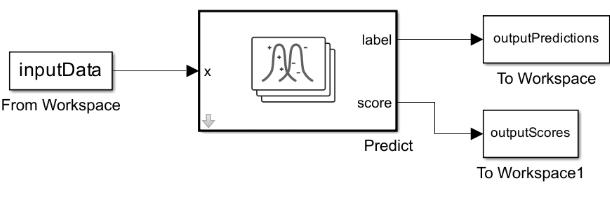

### 5. Test the Simulink Model

Open the Simulink model in Simulink and make a simulation using the default exported testing data (`inputData`), analyze and visualize the results. You do not need to make any modifications in Simulink at this stage. Just run the simulation and analyze/visualize the data. 

Which considerations can you make?

### **6. Make Predictions using New Data**

To make predictions using the new dataset `UNSWNB151 (the one you have modified in the previous paragraph 1) `you have to insert a new input variable in Simulink. Double-click the "Input Data From Workspace" block, and enter the name of the MATLAB variable (based on source file `UNSWNB151`). Before to run the simulation analyze the variable `inputData` and its fields (hint: `inputData.signals.values`) to match the right format.

Simulate the model, analyze and visualize the results. How good was your Simulink prediction?

### Almost at the Finish!

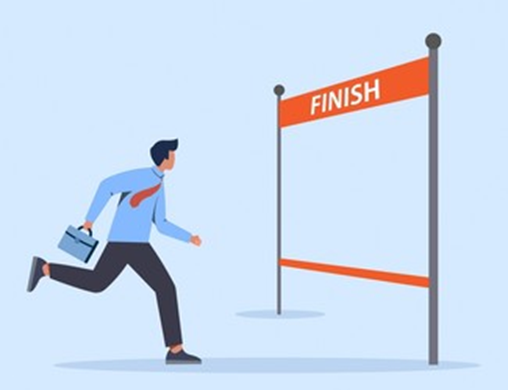

#### Prepare presentation

- Prepare a presentation summarizing your project, highlighting key findings, challenges faced, and solutions implemented.

- Demonstrate the functionality of your Simulink model with a live simulation (video).

- Outlook - With the results achieved, what could be next?

#### Deliver Task! 

- Go to MATLAB Drive: [https://drive.mathworks.com/](https://drive.mathworks.com/) and place your files in a folder 

- Share the folder by: right-clicking the folder, share, create link, copy link

- Check the documentation if you have problems: [Share Folders Using MATLAB Drive](https://nl.mathworks.com/help/matlab/matlab_env/share-and-collaborate-on-matlab-drive.html)

- **Share the hyperlink to your folder in the SANReN CSC Portal**